% =========================================================================
%                       Manuel Santos   2019231352
% =========================================================================

clear; close all; clc;

load("./YaleB.mat");

## Explore data

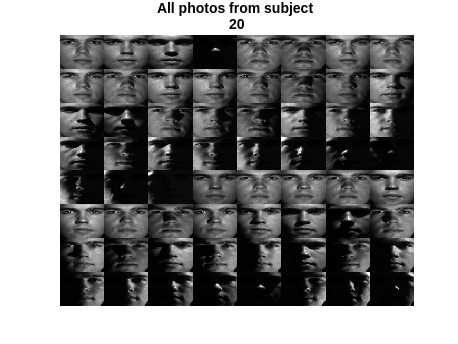

% Show all faces from specific subject
Faces_One = zeros(h_YaleB*8,w_YaleB*8);
count = 1;
person = 20;
for i=1:8
    for j=1:8
        Faces_One(1+(i-1)*h_YaleB:i*h_YaleB,1+(j-1)*w_YaleB:j*w_YaleB) = reshape(allFaces_YaleB(:,64*(person-1)+count),h_YaleB,w_YaleB);
        count = count + 1;
    end
end
figure
imagesc(Faces_One),colormap('gray');
axis off; title(["All photos from subject " num2str(person)])

There are a total of 38 individuals, from 1 to 39 (individual 14 is missing)

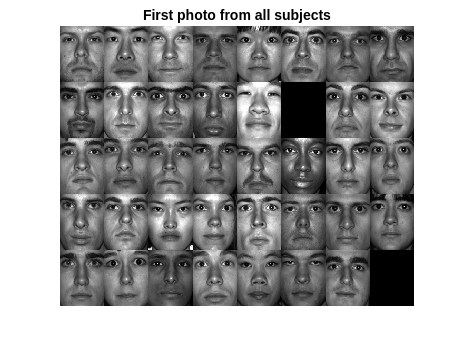

% Show First face of all subjects
Face_One_All = zeros(h_YaleB*5,w_YaleB*8);
count = 1;
for i=1:5
    for j=1:8
        Face_One_All(1+(i-1)*h_YaleB:i*h_YaleB,1+(j-1)*w_YaleB:j*w_YaleB) = reshape(allFaces_YaleB(:,(count-1)*64 + 1),h_YaleB,w_YaleB);
        count = count + 1;
        if count == 40
            break;
        end
    end
end
figure
imagesc(Face_One_All),colormap('gray');
axis off; title("First photo from all subjects")

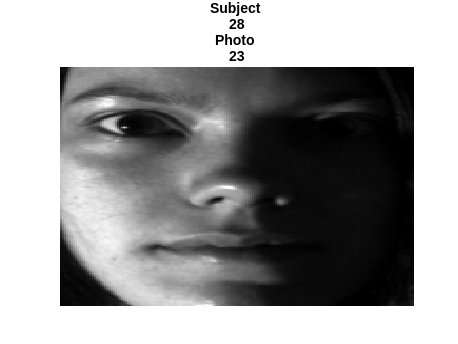

% Show specific face of specific subject
person =28;
photo = 23;
figure
imagesc(reshape(allFaces_YaleB(:,(person-1)*64 + photo),h_YaleB,w_YaleB)); colormap('gray');
axis off; title(["Subject " num2str(person) "Photo " num2str(photo)])

## Split Dataset into Training and Test

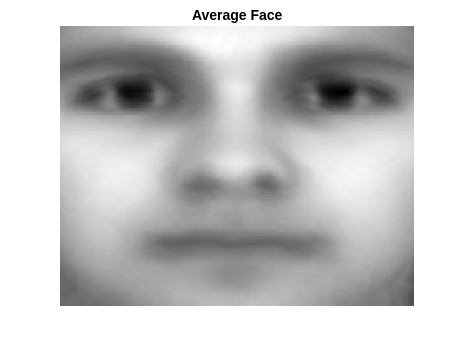

% Select train and test faces
numTrain = 36;
trainFaces = allFaces_YaleB(:,1:numPhotosPerSubject_YaleB*numTrain);
testFaces = allFaces_YaleB(:,numPhotosPerSubject_YaleB*numTrain+1:end);

% Calculate average face
avgFace = mean(trainFaces,2);

% Plot average face
figure
imagesc(reshape(avgFace(:),h_YaleB,w_YaleB));
colormap("gray"); axis off; title("Average Face");

## Calculate SVD

% Calculate SVD
X = double(trainFaces)-avgFace.*ones(size(trainFaces));
[U,S,~] = svd(X,'econ');

## Show obtained Face Space (Eigenfaces)

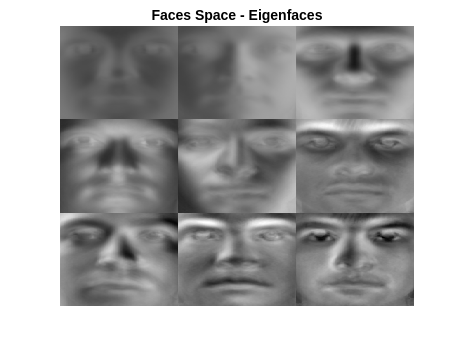

% Plot Eigenfaces
sizeTile = 3;
EigenFaces = zeros(h_YaleB*sizeTile,w_YaleB*sizeTile);
count = 1;
for i=1:sizeTile
    for j=1:sizeTile
        EigenFaces(1+(i-1)*h_YaleB:i*h_YaleB,1+(j-1)*w_YaleB:j*w_YaleB) = reshape(U(:,count),h_YaleB,w_YaleB);
        count = count + 1;
    end
end

% Plot Eigenfaces
figure
imagesc(EigenFaces),colormap('gray');
axis off; title("Faces Space - Eigenfaces");

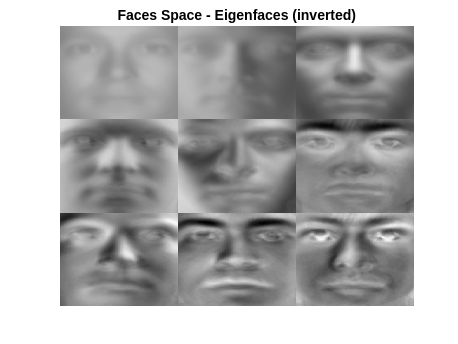


figure
imagesc(EigenFaces.*-1),colormap('gray');
axis off; 
title("Faces Space - Eigenfaces (inverted)");

## Explore Truncation Options

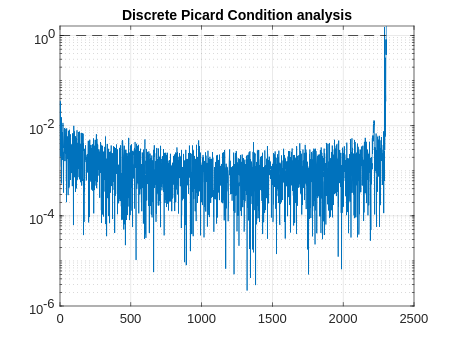

% Try discrete Picard condition
singValues = diag(S);

p = 0;
n = size(singValues,1);
picard = zeros(1,n);
done = false;
for i = 1:n
    picard(i) = (U(:,i)'*avgFace)/singValues(i);
    if abs(picard(i)) <= 1 && ~done
        p = i;
    else
        done = true;
    end
end

figure
semilogy(abs(picard)); grid on; hold on;
plot(ones(1,n),'--k');
title("Discrete Picard Condition analysis");


p

p = 2290

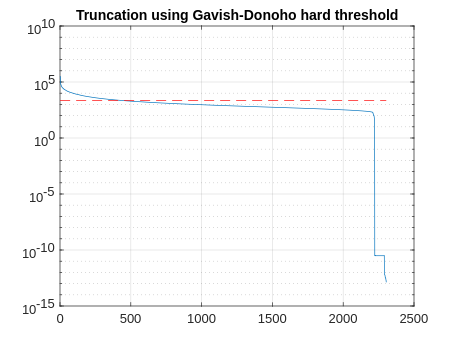

% Try truncation by Gavish-Donoho
figure
semilogy(singValues); grid on; hold on;
title("Truncation using Gavish-Donoho hard threshold");
med = median(singValues);
beta = size(h_YaleB,1) / size(w_YaleB,2);
omega = 0.56*beta^3 - 0.95*beta^2 + 1.82*beta + 1.43;
thres = omega*med;
plot(thres.*ones(1,n),'--r');


idxTrunc = find(singValues>thres);
newP = idxTrunc(end)

newP = 434

## Reconstruct faces using face space

low = round(linspace(10,newP*0.8,3)); sizeU = size(U,2);
high = round(linspace(newP*1.2,sizeU,3));
numEigen = [low newP high];

### Reconstruct training faces

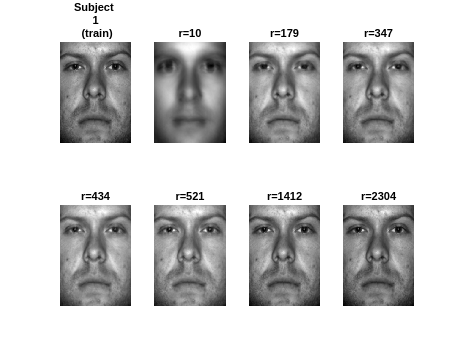

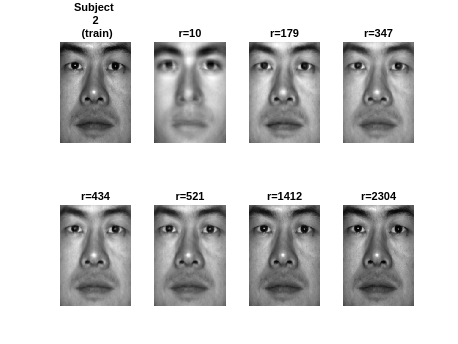

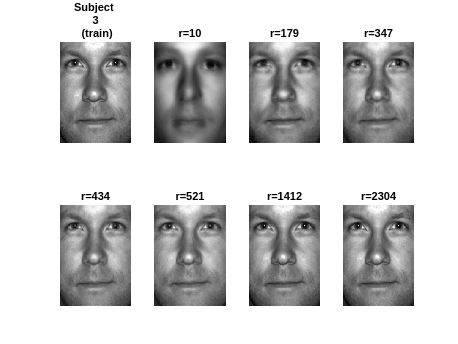

% Reconstruct seen training faces from eigenfaces
 for i = 1:3
    figure
    subplot(2,4,1);
    imagesc(reshape(trainFaces(:,64*(i-1)+1),h_YaleB,w_YaleB));
    colormap("gray"); axis off;
    title(["Subject " num2str(i) " (train)"])
    
    count = 1;
    testFaceMS = double(trainFaces(:,64*(i-1)+1)) - avgFace;
    for j = numEigen
        count = count + 1;
        subplot(2,4,count);
        reconFace = avgFace + (U(:,1:j)*(U(:,1:j)'*testFaceMS));
        imagesc(reshape(reconFace,h_YaleB,w_YaleB));
        colormap("gray"); axis off;
        title(['r=' num2str(j,'%d')]);
    end
 end

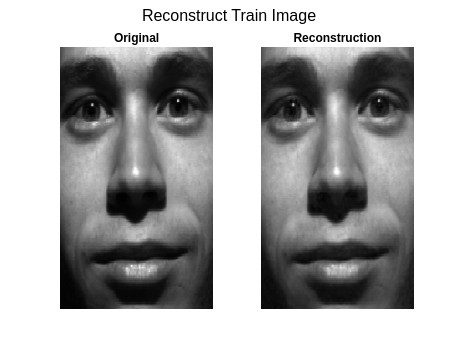

% Interactive reconstruction of train face
figure 
subplot(1,2,1);
imagesc(reshape(trainFaces(:,end-61),h_YaleB,w_YaleB));
colormap("gray"); axis off; title("Original");
testFaceMS = double(trainFaces(:,end-61)) - avgFace;
subplot(1,2,2);
r = 981;
reconFace = avgFace + (U(:,1:r)*(U(:,1:r)'*testFaceMS));
imagesc(reshape(reconFace,h_YaleB,w_YaleB)); axis off; title("Reconstruction");
sgtitle("Reconstruct Train Image");

### Reconstruct test faces

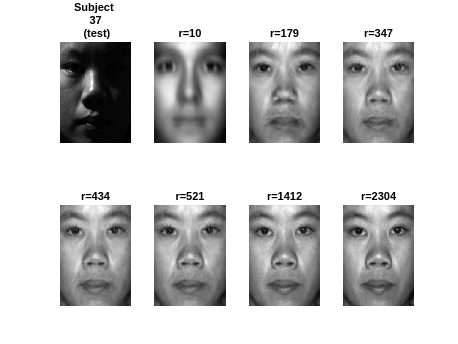

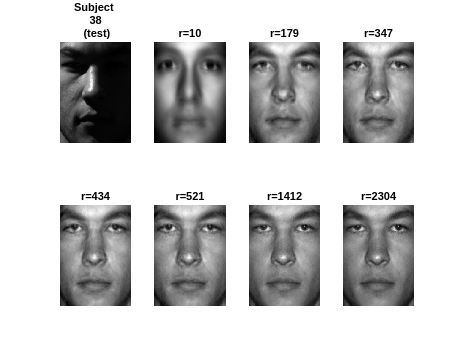

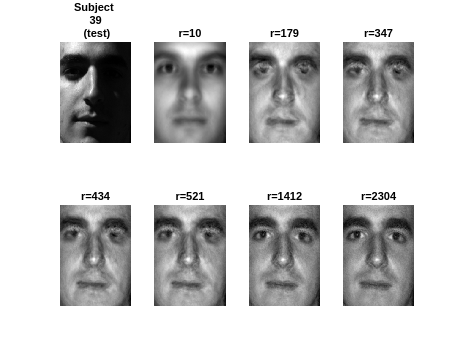

% Reconstruct unseen test faces from eigenfaces
 for i = [0,64,64*2]
    figure
    subplot(2,4,1);
    imagesc(reshape(testFaces(:,i+25),h_YaleB,w_YaleB));
    colormap("gray"); axis off;
    title(["Subject " num2str(37+(i/64)) " (test)"])
    
    count = 1;
    testFaceMS = double(testFaces(:,i+1)) - avgFace;
    for j = numEigen
        count = count + 1;
        subplot(2,4,count);
        reconFace = avgFace + (U(:,1:j)*(U(:,1:j)'*testFaceMS));
        imagesc(reshape(reconFace,h_YaleB,w_YaleB));
        colormap("gray"); axis off;
        title(['r=' num2str(j,'%d')]);
    end
 end

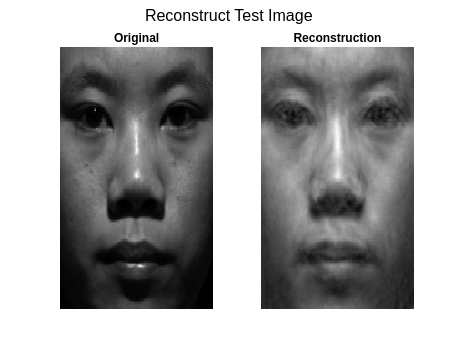

% Interactive reconstruction of test face
figure 
subplot(1,2,1);
imagesc(reshape(testFaces(:,3),h_YaleB,w_YaleB));
colormap("gray"); axis off; title("Original");
testFaceMS = double(testFaces(:,3)) - avgFace;
subplot(1,2,2);
r = 451;
reconFace = avgFace + (U(:,1:r)*(U(:,1:r)'*testFaceMS));
imagesc(reshape(reconFace,h_YaleB,w_YaleB)); axis off; title("Reconstruction");
sgtitle("Reconstruct Test Image");

## Face Recognition

### First test to understand the process

avg_all = mean(allFaces_YaleB,2);

X_all = double(allFaces_YaleB)-avg_all.*ones(size(allFaces_YaleB));
[U_all,S_all,~] = svd(X_all,'econ');

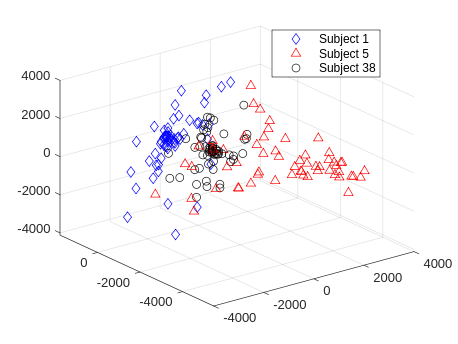

% ==================== Face Recognition ====================

% Change number of images per subject
numImages = 60;

P1 = allFaces_YaleB(:, 64*0+1 : 64*1-(64-numImages)); 
P2 = allFaces_YaleB(:, 64*4+1 : 64*5-(64-numImages));
P3 = allFaces_YaleB(:, 64*37+1 : 64*38-(64-numImages));

P1 = double(P1)-avg_all*ones(1,size(P1,2));
P2 = double(P2)-avg_all*ones(1,size(P2,2));
P3 = double(P3)-avg_all*ones(1,size(P3,2));

% Project onto PCA modes
PCAmodes = [5 6 7 8 9 10 11];

PCACoordsP1 = U_all(:, PCAmodes)' *P1; 
PCACoordsP2 = U_all(:, PCAmodes)' *P2;
PCACoordsP3 = U_all(:, PCAmodes)' *P3;

figure
plot3(PCACoordsP1(1, :), PCACoordsP1(2, :), PCACoordsP1(3,:), 'bd') 
hold on, grid on
plot3(PCACoordsP2(1,:), PCACoordsP2(2,:), PCACoordsP2(3,:), 'r^')
hold on, grid on
plot3(PCACoordsP3(1,:), PCACoordsP3(2,:), PCACoordsP3(3,:), 'ko')
legend('Subject 1', 'Subject 5', 'Subject 38','Location','best')

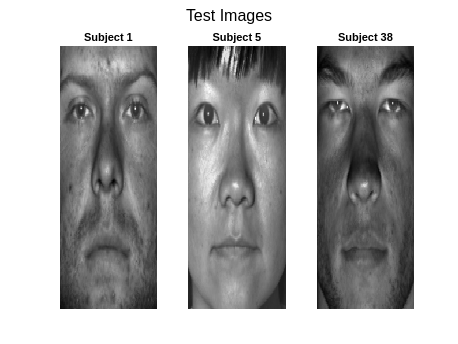


P1_test = allFaces_YaleB(:,64*0+1);
P2_test = allFaces_YaleB(:,64*4+9);
P3_test = allFaces_YaleB(:,64*37+5);

P1_test = double(P1_test)-avg_all*ones(1,size(P1_test,2));
P2_test = double(P2_test)-avg_all*ones(1,size(P2_test,2));
P3_test = double(P3_test)-avg_all*ones(1,size(P3_test,2));

figure
subplot(1,3,1), imagesc (reshape(P1_test(:,1), h_YaleB, w_YaleB)); colormap("gray"), axis off 
title("Subject 1");
subplot(1,3,2), imagesc (reshape(P2_test(:,1), h_YaleB, w_YaleB)); colormap("gray"), axis off
title("Subject 5");
subplot(1,3,3), imagesc (reshape(P3_test(:,1), h_YaleB, w_YaleB)); colormap("gray"), axis off
title("Subject 38");
sgtitle("Test Images");


PCACoordsP1_test = U_all(:, PCAmodes)' *P1_test; 
PCACoordsP2_test = U_all(:, PCAmodes)' *P2_test;
PCACoordsP3_test = U_all(:, PCAmodes)' *P3_test;

d1_1 = mahal(PCACoordsP1_test',PCACoordsP1')

d1_1 = 2.9906

d1_2 = mahal(PCACoordsP1_test',PCACoordsP2')

d1_2 = 13.5937

d1_3 = mahal(PCACoordsP1_test',PCACoordsP3')

d1_3 = 92.1540


d2_1 = mahal(PCACoordsP2_test',PCACoordsP1')

d2_1 = 306.4911

d2_2 = mahal(PCACoordsP2_test',PCACoordsP2')

d2_2 = 5.2171

d2_3 = mahal(PCACoordsP2_test',PCACoordsP3')

d2_3 = 560.8970


d3_1 = mahal(PCACoordsP3_test',PCACoordsP1')

d3_1 = 31.6438

d3_2 = mahal(PCACoordsP3_test',PCACoordsP2')

d3_2 = 4.9025

d3_3 = mahal(PCACoordsP3_test',PCACoordsP3')

d3_3 = 1.8582

### Final Model

P_featureSpace = zeros(length(PCAmodes),60,numSubjects_YaleB,1);
P_test = zeros(length(PCAmodes),4,numSubjects_YaleB);
conf_matrix = zeros(numSubjects_YaleB,numSubjects_YaleB);

for i = 1:numSubjects_YaleB
    idx = randperm(64);
    Px = allFaces_YaleB(:, 64*(i-1)+1:64*(i));
    
    Px_train = Px(:,idx(1:end-4));
    Px_train = double(Px_train)-avg_all*ones(1,size(Px_train,2));
    Px_train_coords = U_all(:, PCAmodes)' *Px_train;
    P_featureSpace(:,:,i) = Px_train_coords;

    Px_test = Px(:,idx(end-3:end));
    Px_test = double(Px_test)-avg_all*ones(1,size(Px_test,2));
    Px_test_coords = U_all(:, PCAmodes)' *Px_test;
    P_test(:,:,i) = Px_test_coords;
end

warning('off'); right = 0; wrong = 0;
for test_subject = 1:size(P_test,3)
    for test_data_of_ID = 1:size(P_test,2)
        prediction = 0;
        distance = Inf;
        for feature_subject = 1:size(P_featureSpace,3)
            d = mahal(P_test(:,test_data_of_ID,test_subject)',P_featureSpace(:,:,feature_subject)');
            if d < distance
                distance = d;
                prediction = feature_subject;
            end
        end
        if prediction == test_subject
            right = right + 1;
%             disp(["RIGHT ->> Subject: " num2str(test_subject) " | Prediction: " num2str(prediction)])
        else
            wrong = wrong + 1;
%             disp(["WRONG ->> Subject: " num2str(test_subject) " | Prediction: " num2str(prediction)])
        end
        conf_matrix(test_subject,prediction) = conf_matrix(test_subject,prediction) + 1;
    end
end

accuracy = right / (size(P_test,2)*size(P_test,3))

accuracy = 0.4474

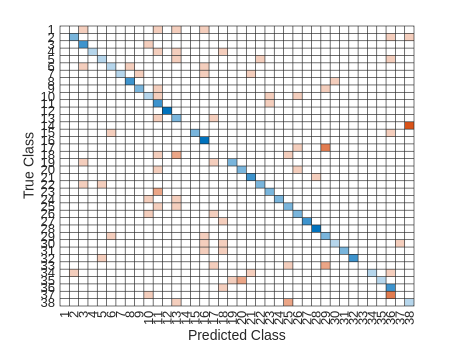

figure
confusionchart(conf_matrix);

## Reconstruct other images

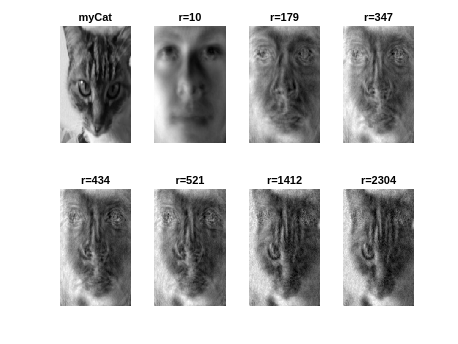

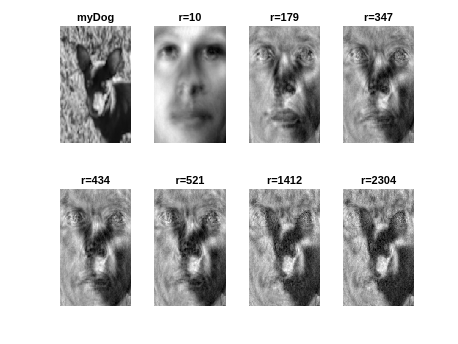

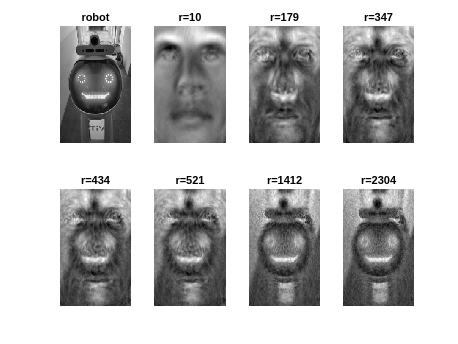

% ==================== Try build several images with Eigenfaces ====================
names = ['myCat';'myDog';'robot']; 

for i = 1:size(names,1)
    test = im2gray(imread(['test_photos/' names(i,:) '.jpg']));
    figure; subplot(2,4,1);imagesc(test); colormap('gray'); axis off;
    title(names(i,:));
    testDone = reshape(test,w_YaleB*h_YaleB,1);
    count = 1;
    testFaceMS = double(testDone) - avgFace;
    for j = numEigen
        count = count + 1;
        subplot(2,4,count);
        reconFace = avgFace + (U(:,1:j)*(U(:,1:j)'*testFaceMS));
        imagesc(reshape(reconFace,h_YaleB,w_YaleB));
        colormap("gray"); axis off;
        title(['r=' num2str(j,'%d')]);
    end
end